# 단순선형회귀분석 

시계열 데이타이지만 각 피쳐와 Capacity는  시계열 모델이 아니라 일반적인 structural 모델이다.

실험결과 선택한 feature 에 따른 선형관계이므로 선택한 feature 의 outer는 제외시켜야 한다.

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

array2table 로 테이블을 만들때 선형회구를 하기 위해 종속변수를 제일 뒤에 두어라

[cap,maxTemp,maxTimeDelta_org,maxTimeDelta,ohm,re_c,re_d] = extract_feature_v2(BAT1);
%maxTimeDelta(abnormal) <= 이상값을 변경하는 것도 필요하다. 차후에.


dataVectorAll = [  maxTimeDelta' maxTemp' ohm'  re_c' re_d' cap'];
dataVector = [  maxTimeDelta' cap'];

%{
[cap2,maxTemp2,maxTimeDelta2_org,maxTimeDelta2,ohm2,re_c2,re_d2] = extract_feature(BAT2);
dataVectorAll2 = [maxTimeDelta2' maxTemp2' ohm2'  re_c2' re_d2' cap2'  ];
dataVector2 = [maxTimeDelta2' cap2'  ];

[cap3,maxTemp3,maxTimeDelta3_org,maxTimeDelta3,ohm3,re_c3,re_d3] = extract_feature(BAT3);
dataVectorAll3 = [maxTimeDelta3' maxTemp3' ohm3'  re_c3' re_d3' cap3'  ];
dataVector3 = [maxTimeDelta3'  cap3'  ];
%}


%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4_org,maxTimeDelta4,ohm4,re_c4,re_d4] = extract_feature(BAT4);
dataVectorAll4 = [maxTimeDelta4' maxTemp4' ohm4'  re_c4' re_d4' cap4'  ];
dataVector4 = [maxTimeDelta4' cap4'  ];
%}

#### 백터를 테이블로 저장하기


tbl = array2table(dataVector,...
    'VariableNames',{'maxTimeDelta','cap'});

% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' cap ~ maxTimeDelta ';
mdl = fitlm(tbl,modelspec )

mdl = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


Number of observations: 169, Error degrees of freedom: 167
Root Mean Squared Error: 0.0146
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 2.87e+04, p-value = 8.78e-189

mdl.Coefficients

ans = 2×4 table
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


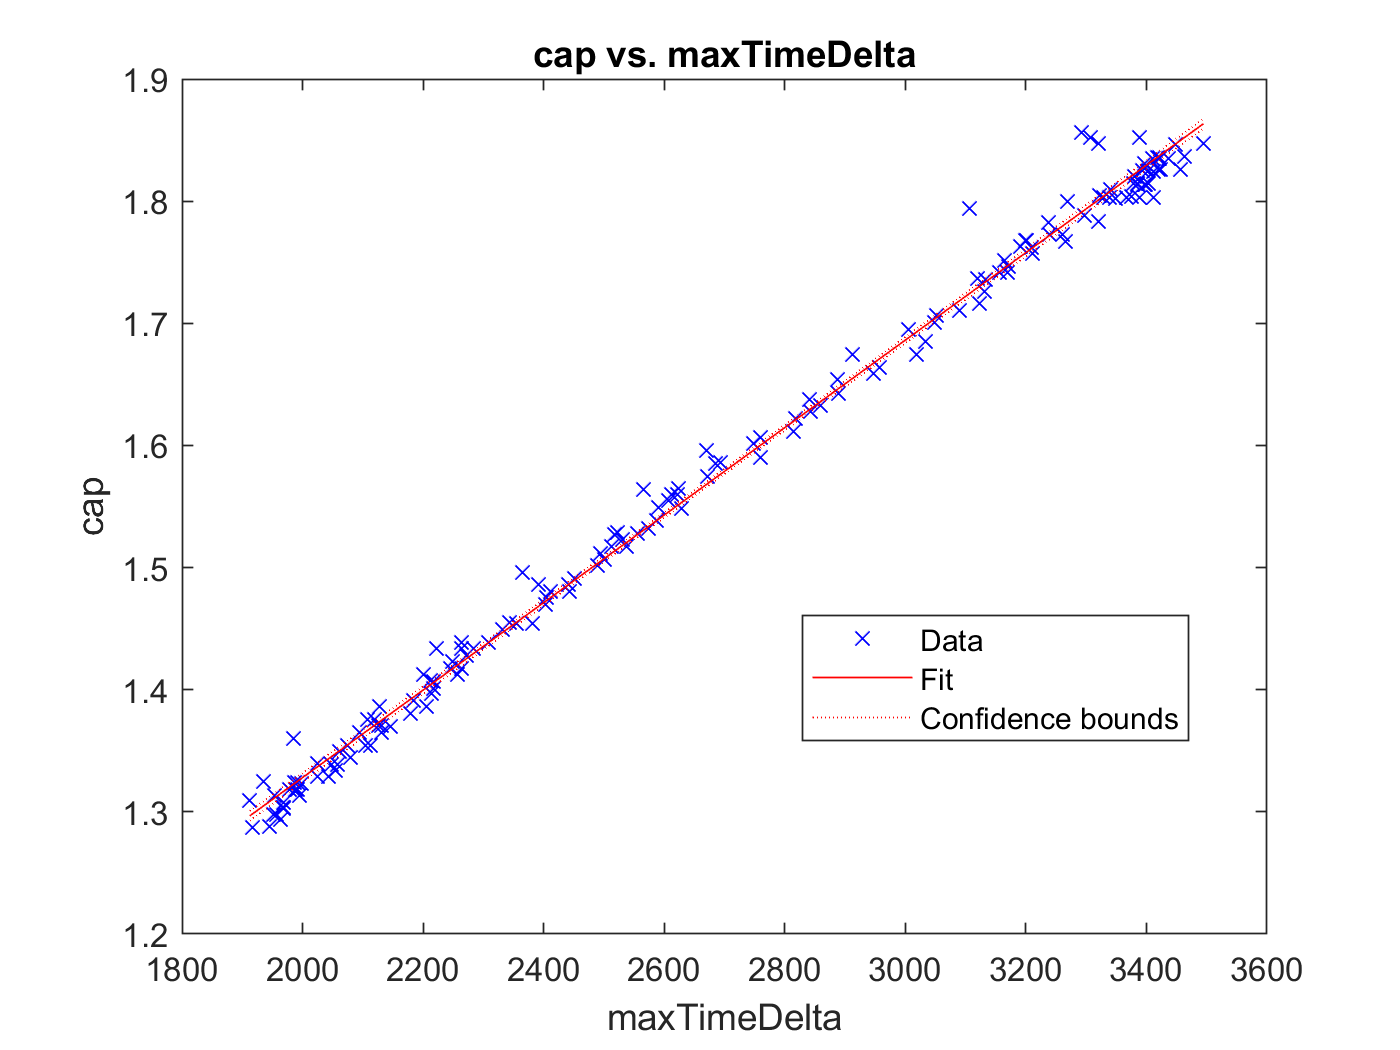

% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(mdl)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차이가 많이 난다.

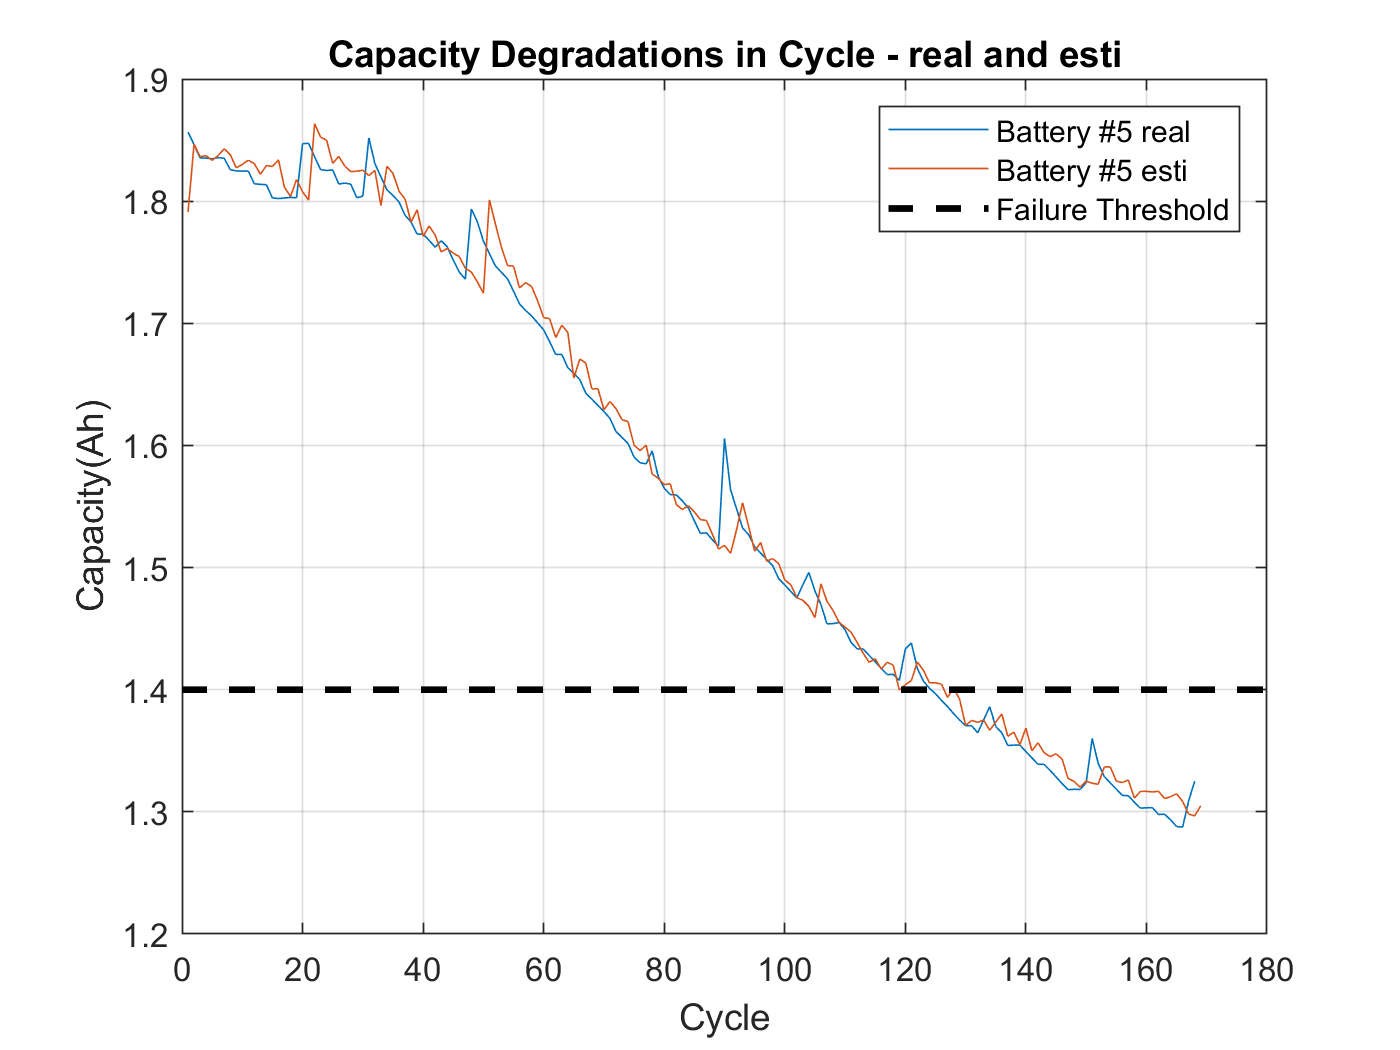


cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

모델설정후 잔차에 대한 히스토그램을 그린다.

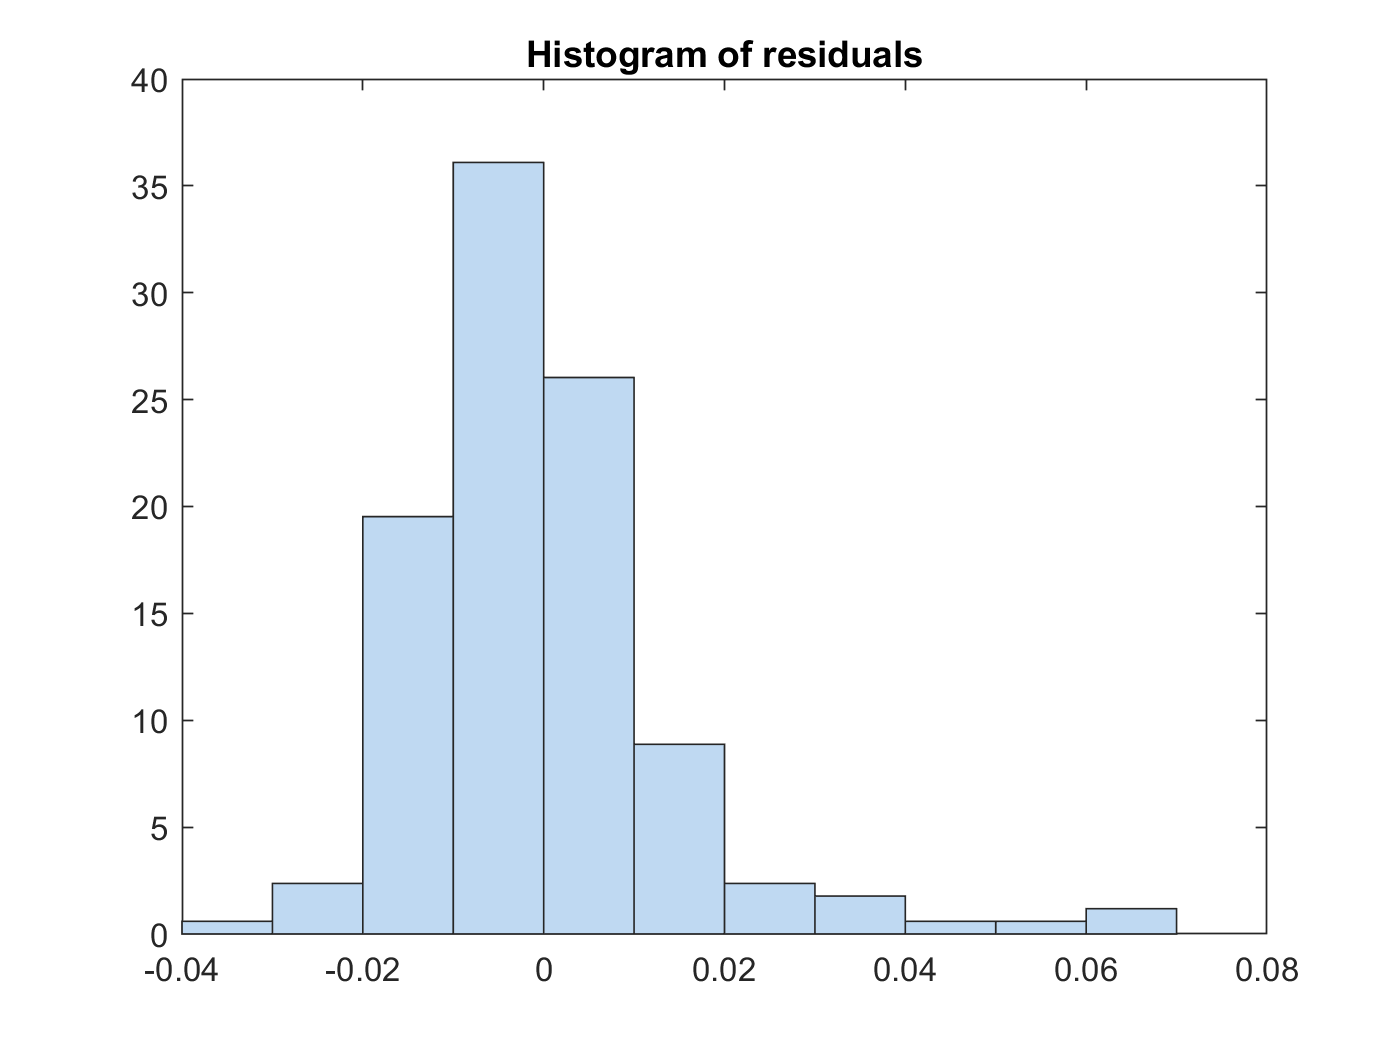

plotResiduals(mdl)

전차가 큰 것이 두개가 보인다. 이를 제거하자

outlier = mdl.Residuals.Raw > 0.04;
find(outlier)

ans =      1
    21
    33
    50


모델에 사용된 데이타에서 outer 를 제외하고 모델링하라.

mdl = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

outer 정보 출력

mdl.ObservationInfo(find(outlier),:)

ans = 4×4 table
    Weights    Excluded    Missing    Subset
    _______    ________    _______    ______

       1        true        false     false 
       1        true        false     false 
       1        true        false     false 
       1        true        false     false 


outer를 제거 후 회귀선이 잘 그려지는지 확인하자.

plot(mdl1)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차기가 많이 줄어들었다.


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

아래는 다변량 선형회귀에서 변수를 줄이기 위한 것이다.

mdl1 = step(mdl,'NSteps',10)

No terms to add to or remove from initial model.


mdl1 = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate        SE        tStat       pValue   
                    __________    _________    ______    ___________

    (Intercept)        0.61803    0.0045164    136.84    3.8132e-170
    maxTimeDelta    0.00035528    1.655e-06    214.68    7.6362e-202


Number of observations: 165, Error degrees of freedom: 163
Root Mean Squared Error: 0.0113
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 4.61e+04, p-value = 7.64e-202

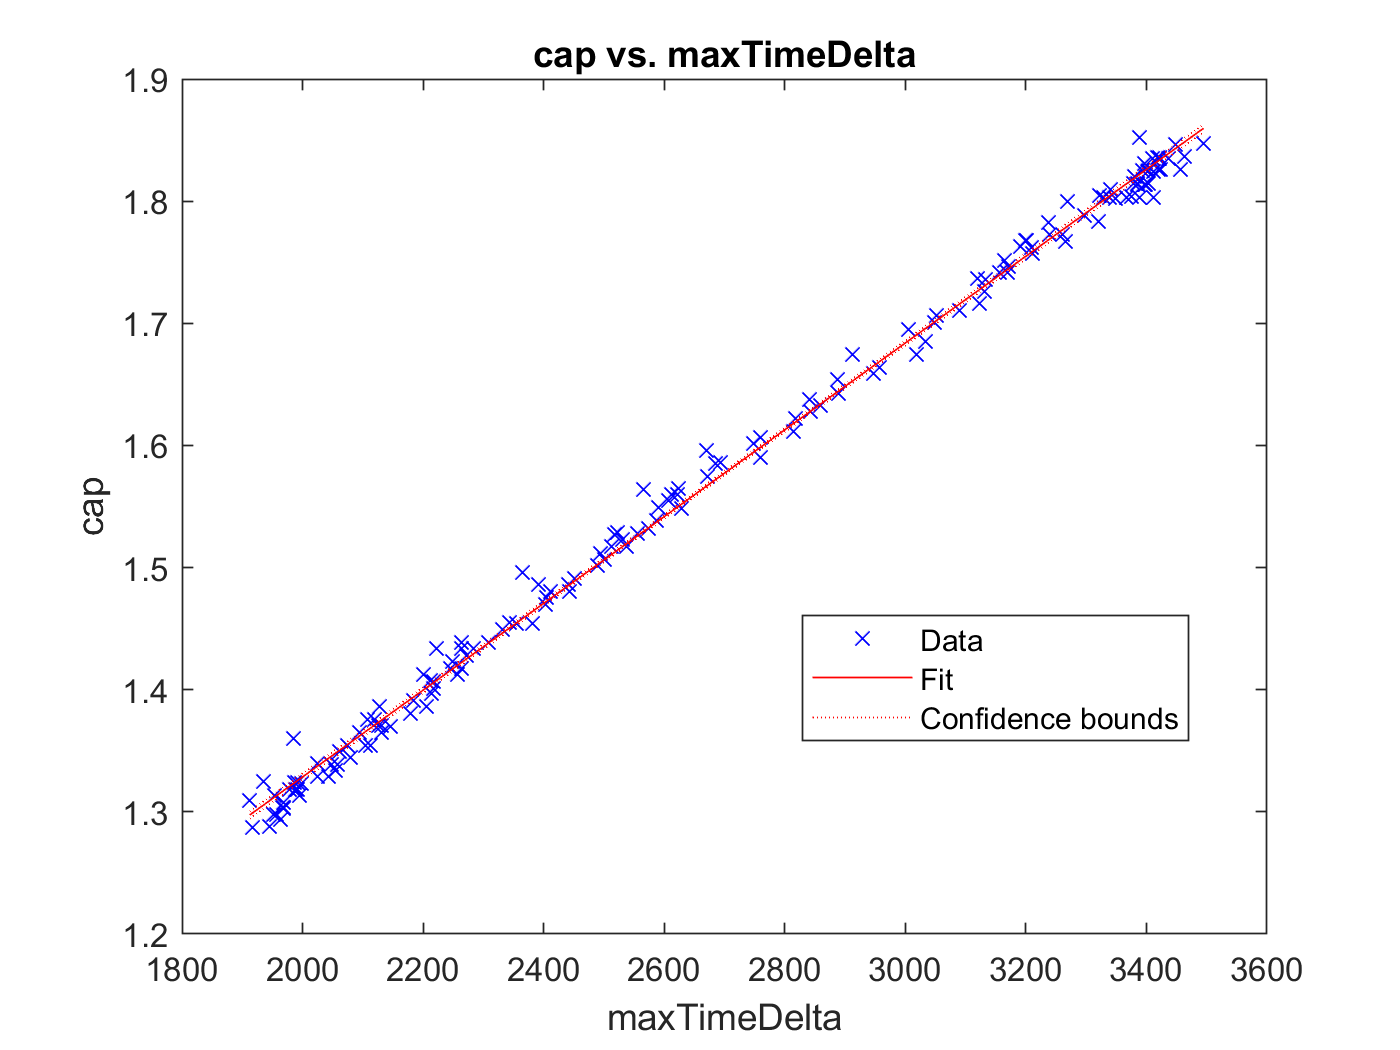

plot(mdl1)

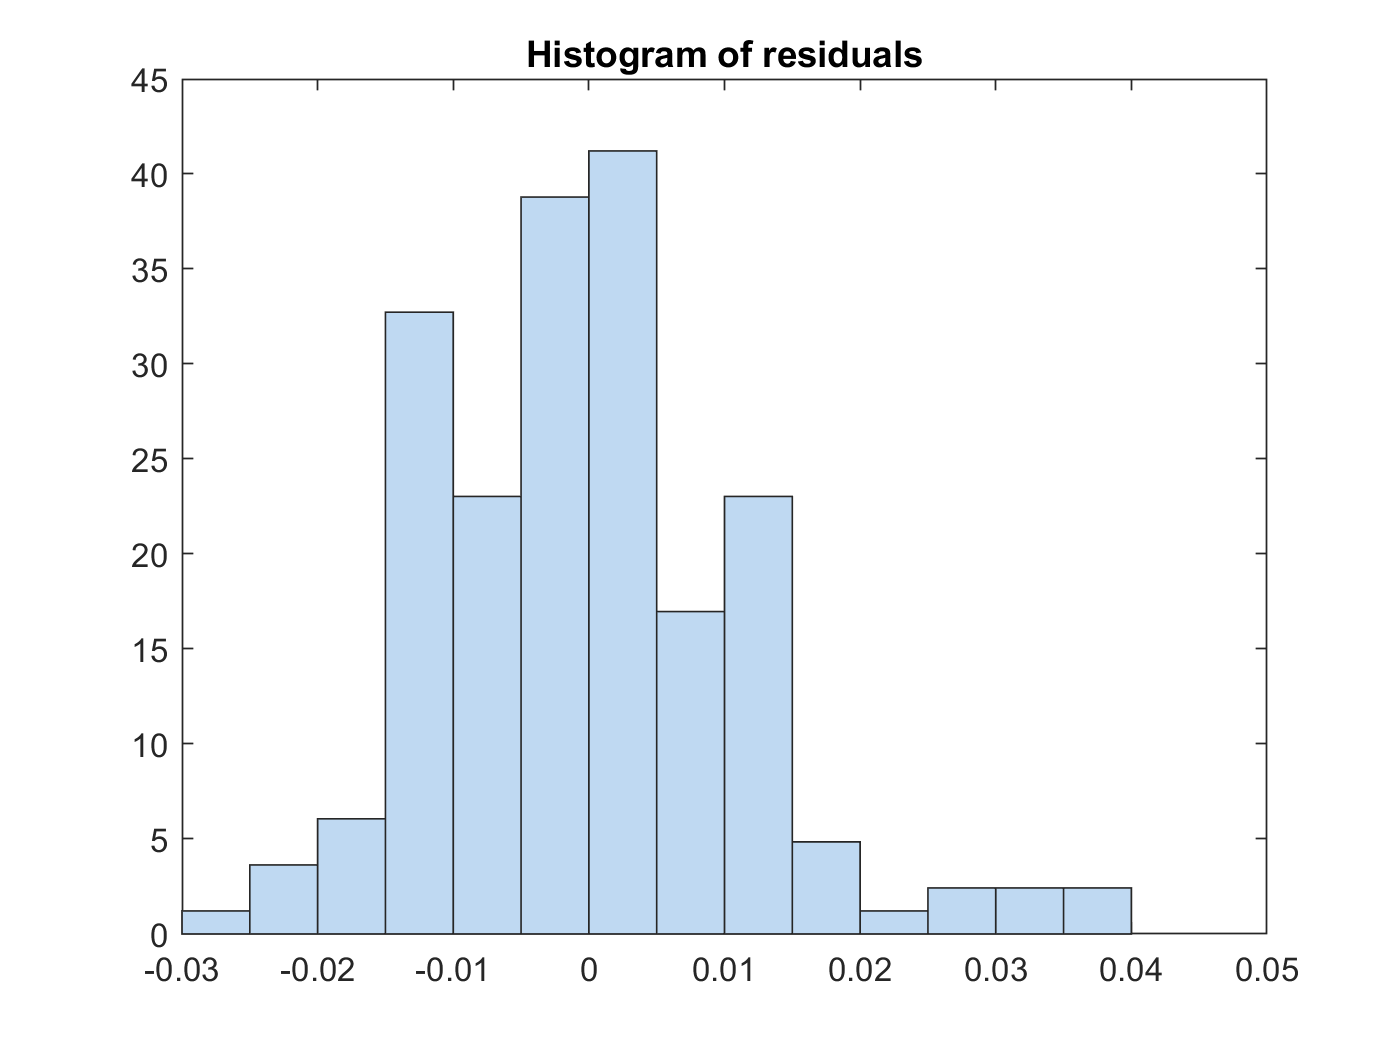

plotResiduals(mdl1)

모델링된 선형회귀식을 가지고 원래 데이타와 예측한 데이타를 비교하자

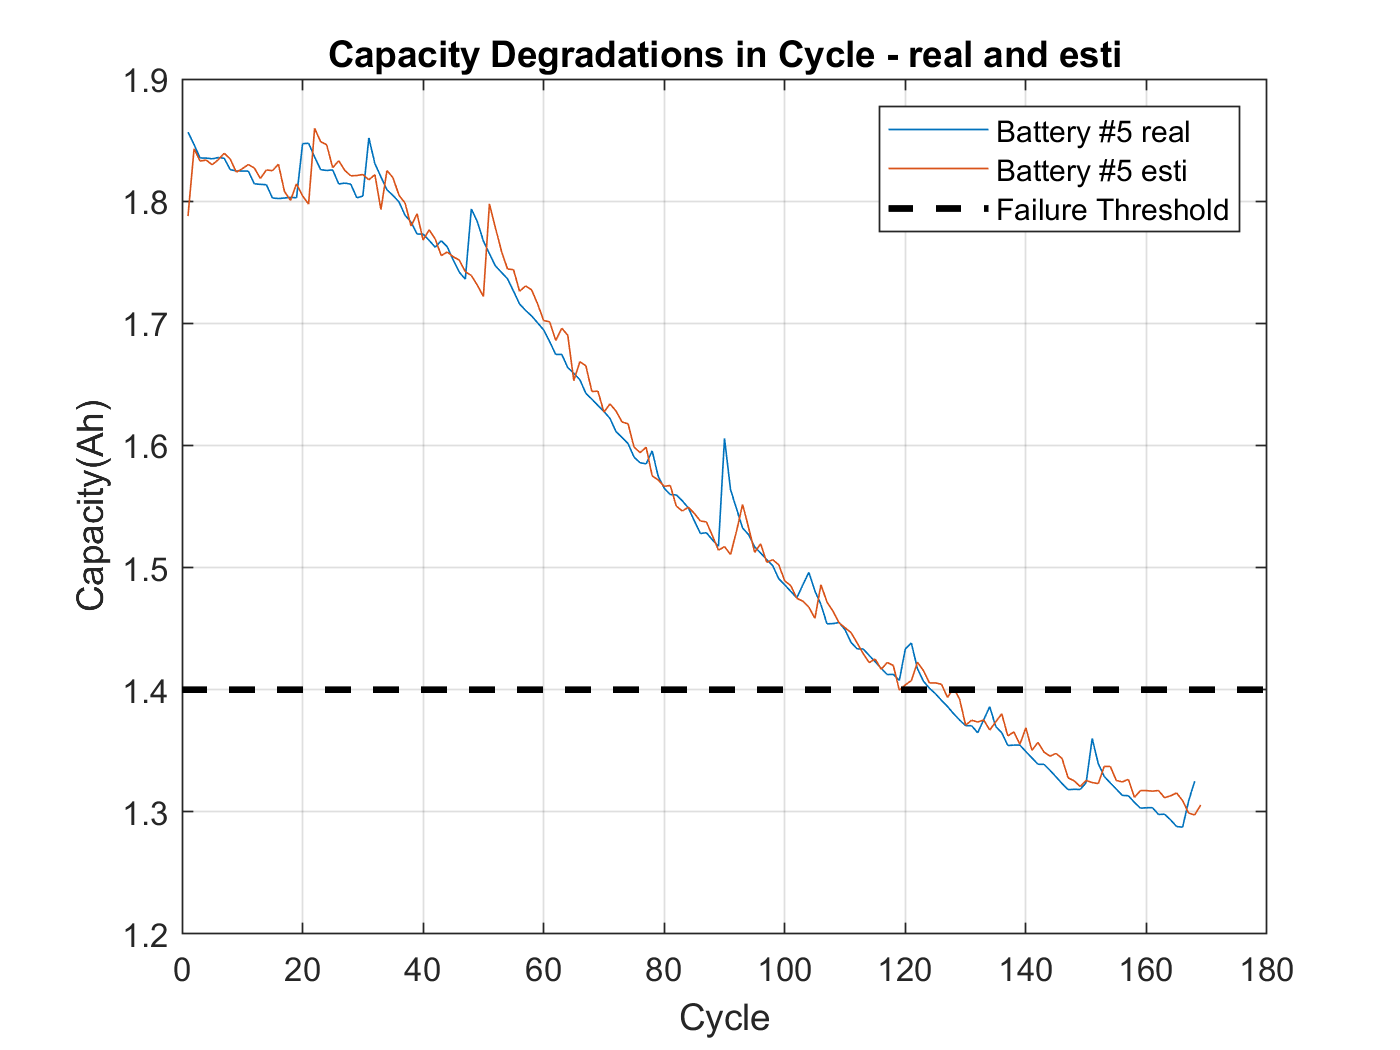


cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09


lm1 = fitlm(tbl,'linear')

lm1 = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


Number of observations: 169, Error degrees of freedom: 167
Root Mean Squared Error: 0.0146
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 2.87e+04, p-value = 8.78e-189

lm2 = fitlm(tbl,'interactions')

lm2 = Linear regression model:
    cap ~ 1 + maxTimeDelta

Estimated Coefficients:
                     Estimate         SE        tStat       pValue   
                    __________    __________    ______    ___________

    (Intercept)        0.61172     0.0057987    105.49    9.3608e-155
    maxTimeDelta    0.00035817    2.1142e-06    169.41    8.7804e-189


Number of observations: 169, Error degrees of freedom: 167
Root Mean Squared Error: 0.0146
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 2.87e+04, p-value = 8.78e-189

lm3 = fitlm(tbl,'purequadratic')

lm3 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTimeDelta^2

Estimated Coefficients:
                       Estimate          SE        tStat       pValue  
                      ___________    __________    ______    __________

    (Intercept)           0.45052      0.039573    11.385    1.4676e-22
    maxTimeDelta       0.00048195    3.0155e-05    15.983    2.0612e-35
    maxTimeDelta^2    -2.2841e-08    5.5521e-09    -4.114    6.1089e-05


Number of observations: 169, Error degrees of freedom: 166
Root Mean Squared Error: 0.014
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 1.57e+04, p-value = 5.91e-190

lm4 = fitlm(tbl,'quadratic')

lm4 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTimeDelta^2

Estimated Coefficients:
                       Estimate          SE        tStat       pValue  
                      ___________    __________    ______    __________

    (Intercept)           0.45052      0.039573    11.385    1.4676e-22
    maxTimeDelta       0.00048195    3.0155e-05    15.983    2.0612e-35
    maxTimeDelta^2    -2.2841e-08    5.5521e-09    -4.114    6.1089e-05


Number of observations: 169, Error degrees of freedom: 166
Root Mean Squared Error: 0.014
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 1.57e+04, p-value = 5.91e-190

%lm5 = fitlm(tbl,'polyi13')

testend =1;